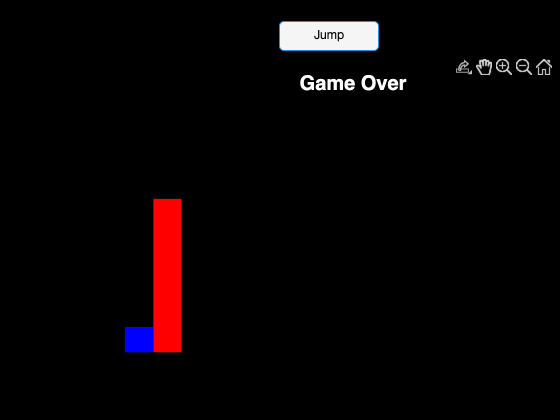

%% Geometry Dash Mini (Live Script Version)

% Clear and setup figure
clear; close all; clc;

fig = uifigure('Name', 'Geometry Dash Mini'); % UI Figure for live script compatibility
ax = uiaxes(fig, 'Position', [50 50 600 300]);
axis(ax, [0 100 0 50]);
hold(ax, 'on');
ax.XColor = 'none';
ax.YColor = 'none';
ax.Color = 'k';
fig.Color = 'k';

% Add Jump Button
jumpButton = uibutton(fig, 'Text', 'Jump', 'Position', [280 370 100 30]);

% Player properties
player.width = 5;
player.height = 5;
player.x = 10;
player.y = 10;
player.velocityY = 0;
gravity = -0.5;
jumpVelocity = 8;

% Obstacle properties
obstacles = struct('x', {}, 'y', {}, 'width', {}, 'height', {});
spawnTimer = 0;

% Draw player
playerRect = rectangle(ax, 'Position', [player.x player.y player.width player.height], 'FaceColor', 'b');

% Game control
running = true;

% Set jump function
jumpButton.ButtonPushedFcn = @(btn,event) jump();

%% Main Game Loop
while running && isvalid(fig)
    % Update player physics
    player.velocityY = player.velocityY + gravity;
    player.y = player.y + player.velocityY;
    
    if player.y <= 0
        player.y = 0;
        player.velocityY = 0;
    end
    
    % Update player drawing
    playerRect.Position = [player.x player.y player.width player.height];
    
    % Spawn obstacles
    spawnTimer = spawnTimer + 1;
    if spawnTimer > 100
        spawnTimer = 0;
        newObstacle.x = 100;
        newObstacle.y = 0;
        newObstacle.width = 5;
        newObstacle.height = 10 + randi(20);
        obstacles(end+1) = newObstacle;
    end
    
    % Move and update obstacles
    for i = 1:length(obstacles)
        obstacles(i).x = obstacles(i).x - 1;
    end
    
    % Delete offscreen obstacles
    obstacles = obstacles([obstacles.x] > -5);
    
    % Redraw obstacles
    delete(findobj(ax, 'Tag', 'obstacle'));
    for i = 1:length(obstacles)
        rectangle(ax, 'Position', [obstacles(i).x obstacles(i).y obstacles(i).width obstacles(i).height], ...
            'FaceColor', 'r', 'Tag', 'obstacle');
    end
    
    % Check collision
    for i = 1:length(obstacles)
        if rectsCollide(player, obstacles(i))
            running = false;
            title(ax, 'Game Over', 'Color', 'w', 'FontSize', 20);
            break;
        end
    end
    
    pause(0.03); % Frame pause
end


%% Jump Function
function jump()
    player = evalin('base', 'player');
    if player.y == 0
        player.velocityY = 8; % Jump up
        assignin('base', 'player', player);
    end
end

%% Collision Function
function result = rectsCollide(a, b)
    result = ~(a.x + a.width < b.x || a.x > b.x + b.width || ...
               a.y + a.height < b.y || a.y > b.y + b.height);
end